## **Visualization of prediction performances (Basic NMA Model and Expanded NMA Model)  **

Creation of bar plots used to visualize the prediction performances of the internal cross-validation in the main sample and the cross-sample model generalization test from the main sample to the lockbox sample (HCP532 --> HCP232). This scitp also visualizes the individual datapoints and the standard error. 

Before running this script: 

- Run all scripts in HCP Data prep and the scripts used to compute the prediction performances of the models that are plotted here.

1. Load in the prediction performances (change input values for internal CV/external CV)

prediction_performances = [all_rhos_final_correlations_RES, all_rhos_final_correlations_EMO, all_rhos_final_correlations_GAM, all_rhos_final_correlations_LAN, all_rhos_final_correlations_MOT, all_rhos_final_correlations_REL, all_rhos_final_correlations_SOC, all_rhos_final_correlations_WM, all_rhos_final_correlations_ALL]

prediction_performances =     0.1614    0.0114    0.0427    0.1904    0.0931    0.1281    0.2246    0.1138    0.2035
    0.1550    0.0009    0.0455    0.1950    0.0753    0.1422    0.2268    0.1052    0.1951
    0.1488    0.0215    0.0637    0.1941    0.0926    0.1313    0.2192    0.1010    0.1878
    0.1520    0.0044    0.0442    0.1877    0.0747    0.1335    0.2350    0.1112    0.1959
    0.1528    0.0094    0.0541    0.1952    0.0784    0.1299    0.2216    0.1091    0.1940
    0.1579    0.0035    0.0443    0.1863    0.0795    0.1317    0.2306    0.1048    0.2065
    0.1535   -0.0032    0.0321    0.1919    0.0768    0.1399    0.2298    0.1017    0.2096
    0.1581   -0.0116    0.0379    0.1935    0.0824    0.1328    0.2249    0.1054    0.2048
    0.1525    0.0024    0.0414    0.1939    0.0794    0.1300    0.2240    0.1031    0.1996
    0.1523    0.0189    0.0471    0.1735    0.0909    0.1191    0.2209    0.1067    0.2011


2. Compute the means 

means = mean(prediction_performances)

means =     0.1533    0.0032    0.0461    0.1877    0.0841    0.1315    0.2252    0.1054    0.1992


3. Compute standard error

stds = std(prediction_performances);
n = size(prediction_performances,1); % sample size
SE = stds ./ sqrt(n); % compute standard error

4. Barplot 

figure;
bar_handle = bar(means, 'FaceColor', 'flat');
hold on;

% Change color of individual bars

bar_handle.FaceColor = 'flat'

bar_handle =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9]
        YData: [0.1533 0.0032 0.0461 0.1877 0.0841 0.1315 0.2252 0.1054 0.1992]

  Show all properties


bar_handle.FaceAlpha = 0.75

bar_handle =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9]
        YData: [0.1533 0.0032 0.0461 0.1877 0.0841 0.1315 0.2252 0.1054 0.1992]

  Show all properties


bar_handle.CData(1,:) = [0 0.4470 0.7410];
bar_handle.CData(2,:) = [0.8500 0.3250 0.0980];
bar_handle.CData(3,:) = [0.9290 0.6940 0.1250];
bar_handle.CData(4,:) = [0.4940 0.1840 0.5560];
bar_handle.CData(5,:) = [0.4660 0.6740 0.1880];
bar_handle.CData(6,:) = [0.3010 0.7450 0.9330];
bar_handle.CData(7,:) = [0.6350 0.0780 0.1840];
bar_handle.CData(8,:) = [0.1350 0.2780 0.2410];
bar_handle.CData(9,:) = [0.2 0.3 0.4];

5. Individual datapoints

numModels = size(prediction_performances, 2);% number of prediction models
x_offsets = linspace(-0.2, 0.2, size(prediction_performances,1)); % small distributions of scatter

for i = 1:numModels
    scatter(ones(size(prediction_performances,1),1) * i + x_offsets', prediction_performances(:,i), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.2,'MarkerEdgeColor', 'k','MarkerEdgeAlpha', 0.5);
end

6. Include standard error

errorbar(1:numModels, means, SE, 'k', 'linestyle', 'none', 'linewidth', 1.5);

7. Achses and title

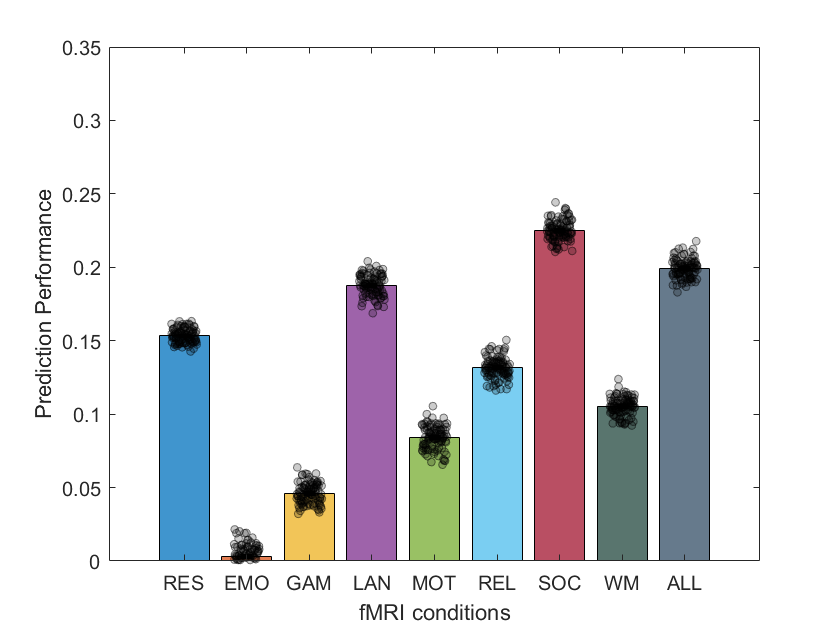

xticks(1:numModels);
xticklabels({'RES', 'EMO', 'GAM', 'LAN', 'MOT', 'REL', 'SOC', 'WM', 'ALL'}); % Labels for 9 models
ylabel('Prediction Performance');
ylim([0 0.35]);
xlabel('fMRI conditions')
% title('Model Comparison: Prediction Performance');
hold off;